% CROP FOV


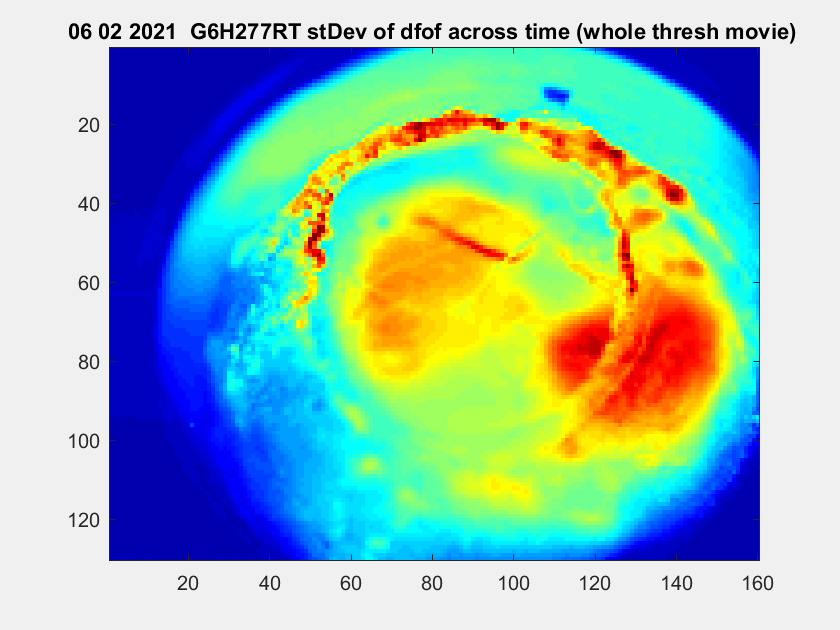

% 1st step: PICK image TO CROP from DF
% std of df gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames of df (don't need all, why?). taking std across 3rd dimension, time
figure;
range = [0 0.07];
colormap jet
imagesc(stdMap,range)% 
clear titleText
titleText = 'stDev of dfof across time (whole thresh movie)';
title(sprintf('%s ',date,subjName,titleText))

% DO the CROP
% crop manually by picking top left and then bottom right corners of a rectangle
[xPtsCrop_VIS_CTX_ONLY yPtsCrop_VIS_CTX_ONLY] = ginput(2);

df_VIS_CTX_ONLY = df(yPtsCrop_VIS_CTX_ONLY(1):yPtsCrop_VIS_CTX_ONLY(2),xPtsCrop_VIS_CTX_ONLY(1):xPtsCrop_VIS_CTX_ONLY(2),:); % cropping df to be area I select 

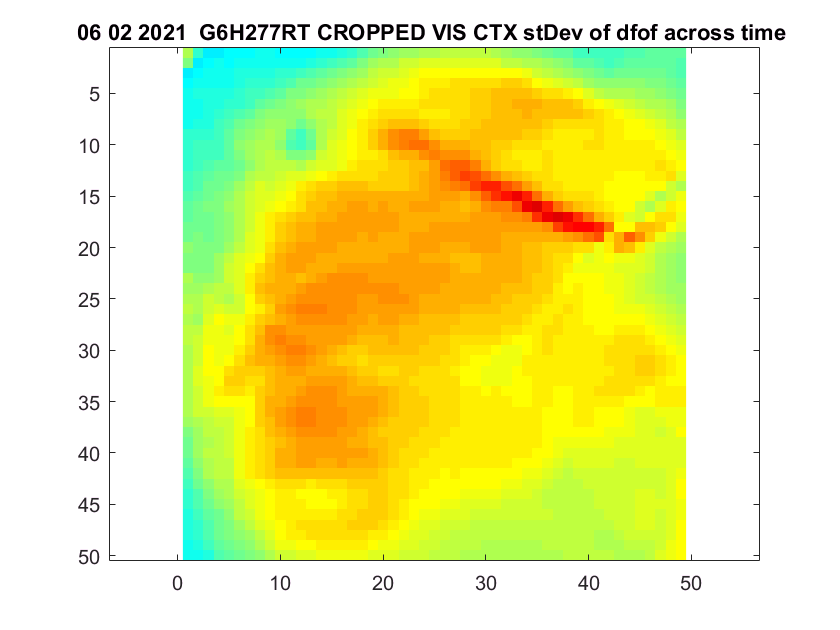


% SHOW the CROPPED image� 
stdMap = std(df_VIS_CTX_ONLY(:,:,1:10:end),[],3); 
figure
colormap jet
imagesc(stdMap,[0 0.07])
axis equal
clear titleText
titleText = 'CROPPED VIS CTX stDev of dfof across time';
title(sprintf('%s ',date,subjName,titleText))

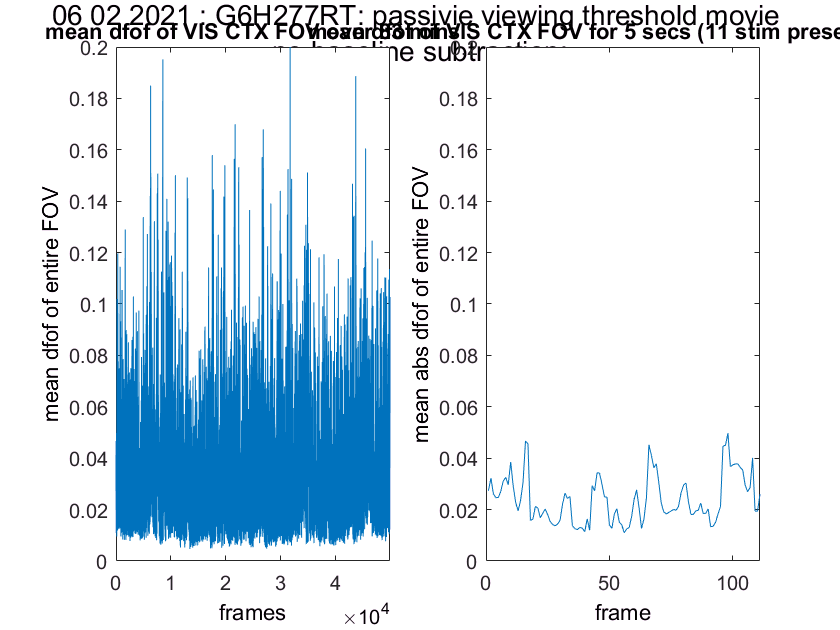

% BROAD look at ACTIVITY over WHOLE FOV

titleText = sprintf('passivie viewing threshold movie \n no baseline subtraction');
clear t
t = suptitle(sprintf('%s: ',date,subjName,titleText));
%set(t, 'FontSize', 12);

clear j
for j = 1:2; % for 2 figures
    if j == 1
        % taking the average of the entire imaging field over WHOLE TIME
        mn = mean(mean(abs(df_VIS_CTX_ONLY),2),1); 
        mn = squeeze(mn);
        % plot
        subplot(1,2,j)
        plot(squeeze(mn));  
        xlim([0 size(squeeze(mn),1)])  
        ylim([0 0.2])
        xlabel('frames')
        ylabel('mean dfof of entire FOV') 
        clear numFrames4title
        numFrames4title = length(mn); 
        clear numSecs4title
        numMins4title = (numFrames4title/10/60);
        title(sprintf('mean dfof of VIS CTX FOV over %0.00f mins',numMins4title))
    end 
    if j == 2
        % let's look at that average trace over a time scale closer 
        % to our AVG TRIAL LENGTH, ~2,2s / 22 imaging frames
        sqMn = squeeze(mn); % getting rid of singletons
        trSqMn = sqMn'; % transposing
        % select only 111 frames - 111/22 = roughly 5 stim presentations
        fiveStimsTrSqMn = trSqMn(1,1:111);
        numStimPresentations = 5;
        % plot
        subplot(1,2,j)
        plot(fiveStimsTrSqMn ); 
        xlim([0 length(fiveStimsTrSqMn)])
        ylim([0 0.2])
        ylabel('mean abs dfof of entire FOV') 
        xlabel('frame') 
        clear numFrames4title
        numFrames4title = length(fiveStimsTrSqMn); 
        clear numSecs4title
        numSecs4title = (numFrames4title/10);
        title(sprintf('mean dfof of VIS CTX FOV for %0.00f secs (%0.00f stim presentations)',numStimPresentations,numSecs4title)); 
    end 
end 

% making variable 'onsetDf'
% using onsetFrames to index into dF % take 'chunks' of video around each stim onset
clear i
clear onsetDf2

for i = 1:length(onsetFrame)
    % then select only the imaging frames right before & after the onset imaging frame of each stim
    onsetDf2(:,:,:,i) = df_VIS_CTX_ONLY(:,:,onsetFrame(i)-numPreStimFrames:onsetFrame(i)+numPostStimFrames);
end
size(onsetDf2)

ans =           50          49          23        1638


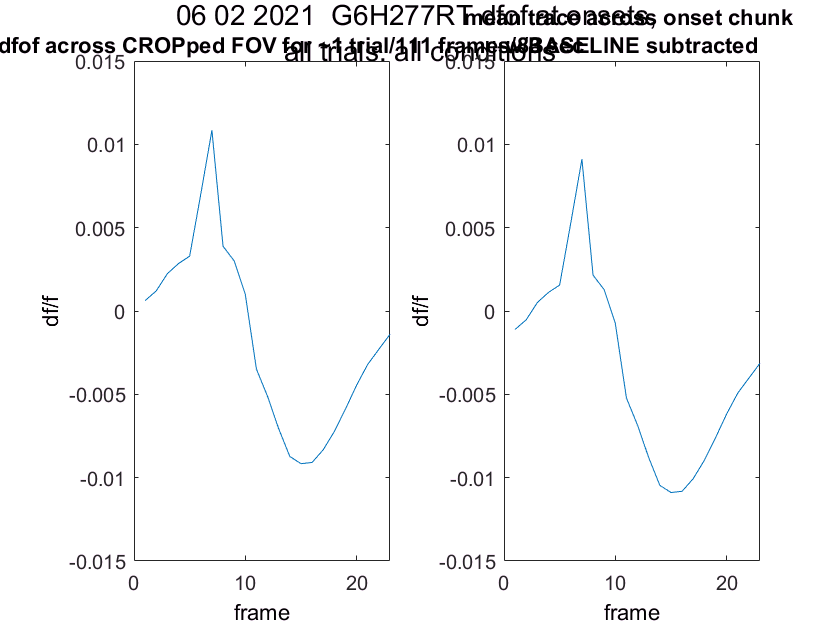

%% looking at the average trace over time for onsetFrame
% PRE & POST BASELINE

% mean across whole image, all trials/conditions
mnOnsetChunk = mean(squeeze(mean(squeeze(mean(onsetDf2,1)))),2)';

numFrames = length(mnOnsetChunk);
numSec = (numFrames)*0.1;

figure

clear titleText
titleText = sprintf('dfof at onsets, \n all trials, all conditions');
suptitle(sprintf('%s ',date,subjName,titleText))

for j = 1:2 % pre & post baselined plots
    
    if j == 1
        
        % plot mean chunk trace
        subplot(1,2,j)
        plot(mnOnsetChunk)
        ylim([-0.015 0.015])
        xlim([0 numFrames])
        xlabel('frame') 
        ylabel('df/f')
        clear titleText
        titleText = sprintf('mean dfof across CROPped FOV for ~1 trial/%0.00f frames/%0.00f sec',numFrames4title,numMins4title);
        title(sprintf('%s ',titleText))

    end 

    if j == 2  
        
        % index into just the baseline frames of the mean chunk
        allBaseMnOnsetChunk = mnOnsetChunk(1,baselineIdx);
        % get mean for 1st 4 frames
        meanBaseOnsetChunk = mean(allBaseMnOnsetChunk,2);
        %subtract mean from each cell in mnChunkOnset vector
        baselinedMnOnsetChunk = mnOnsetChunk-meanBaseOnsetChunk;
        % plot
        clear x_axis
        x_axis = 1:length(baselinedMnOnsetChunk);
        subplot(1,2,j)
        plot(x_axis,baselinedMnOnsetChunk)
        ylim([-0.015 0.015])
        xlim([0 numFrames])
        xlabel('frame') 
        ylabel('df/f')
        clear titleText
        titleText = sprintf('mean trace across onset chunk \n w/BASELINE subtracted');
        title(sprintf('%s ',titleText))
        
    end
    
end